# Slosh 3D - Tilting about y 

YX parametrization of the pendulum

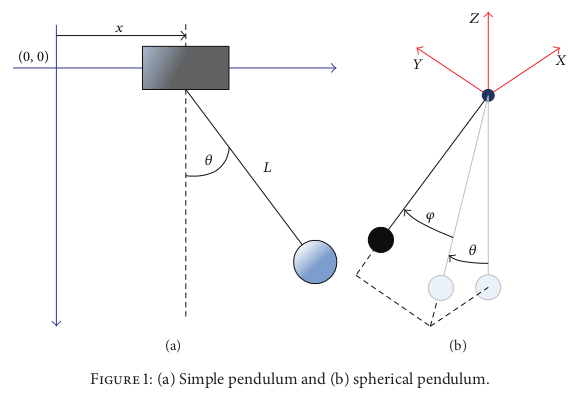

In this code the equation of motion for the pendulum angle representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent only the 3D motion of the tray and a 1D rotation about the y axis of the container.

clc 
clear all

syms theta(t) psi(t) phi(t) beta(t)
syms t 
syms d_n h l_n m_n g M b
syms x(t) y(t) z(t)
sympref('AbbreviateOutput',false);

assume(h > 0)
assume(m_n > 0)
assume(g > 0)
assume(l_n > 0)

rot = "y"

rot = "y"

matlab_function_generation = true;

$\theta$ = angle between plane ZY and the mass, angle of the pendulum mapped in xz plane

$\phi$ = angle in the perpendicular direction, between the original pendulum and the mapped pendulum

$\beta$ = pitch rotation about the y axis of the container

h = height of the container

d = distance from CoR to pendulum pivot (if in CoM: h/2 - Ln, if at base of container: h - Ln)

l_n = length of pendulum

m = mass of pendulum

M = mass of liquid + container

b = damping coefficient

J = moment of inertia of the pendulum mass

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid+container mass in the world reference frame.

Assume the following reference frames:

- Inertial frame

- Frame of the container CoR with origin assumed to be at a distance d from the pivot

- Frame of the pivot of the pendulum

- Frame of the pendulum mass

### World to CoM

Derive the homogeneous transformation matrix from the world to the CoM reference frame.

Define rotation matrix (rotation of around the y-axis)

% Rotation matrix about y-axis of angle beta
R_y_beta = [cos(beta),  0, sin(beta); 
             0,           1,           0; 
             -sin(beta),  0,  cos(beta)];
R_y_beta=formula(R_y_beta)

$$R\_y\_beta = \left(\begin{array}{ccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [x; y; z];

Create homogeneous transformation matrix

T_wg = [R_y_beta, p; 0 0 0 1];
T_wg = formula(T_wg);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to CoM:');

Homogeneous Transformation Matrix from world to CoM:


disp(T_wg);

$$\left(\begin{array}{cccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right) & x\left(t\right)\\ 0 & 1 & 0 & y\left(t\right)\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### CoM to pivot

Derive the homogeneous transformation matrix from the CoM reference frame to the pivot reference frame.

Define rotation matrices

% Rotation matrix about y-axis of angle -theta
R_y_theta = [cos(theta),  0, sin(theta); 
             0,           1,           0; 
             -sin(theta),  0,  cos(theta)];
R_y_theta = formula(R_y_theta)

$$R\_y\_theta = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & \sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$


% Rotation matrix about x-axis of angle phi
R_x_phi = [1,          0,          0; 
           0,   cos(phi),  -sin(phi); 
           0,   sin(phi),  cos(phi)];
R_x_phi=formula(R_x_phi)

$$R\_x\_phi = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ 0 & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$


R_combined = R_y_theta * R_x_phi 

$$R\_combined = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ -\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector (from the CoM reference frame)

p = [0; 0; d_n];

Create homogeneous transformation matrix

T_gp = [R_combined, p; 0 0 0 1];
T_gp = formula(T_gp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from liquid to pivot:');

Homogeneous Transformation Matrix from liquid to pivot:


disp(T_gp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & 0\\ -\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & d_{n}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pivot to Pendulum mass

R = eye(3)

R =      1     0     0
     0     1     0
     0     0     1


Define translation vector

p = [0; 0; -l_n];

Define the position of the pendulum mass in the static reference frame fixed to the pivot

T_pm = [R, p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l_{n}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$p_m =$$

$$\left(\begin{array}{c}
l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\\
l\,\sin \left(\phi \left(t\right)\right)\\
-l\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wg*T_gp*T_pm

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+d_{n}\,\sin\left(\beta \left(t\right)\right)-l_{n}\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)+l_{n}\,\sin\left(\varphi \left(t\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l_{n}\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)+d_{n}\,\cos\left(\beta \left(t\right)\right)$$

Coordinates of pendulum mass relative to the pivot

% xr = xm - x
% yr = ym - y
% zr = zm - z

% % if theta = -
% xr = l_n*cos(phi)*sin(theta);
% yr = l_n*sin(phi);
% zr = -l_n*cos(phi)*cos(theta);

% if theta = +
xr = l_n*cos(phi)*sin(theta);
yr = l_n*sin(phi);
zr = -l_n*cos(phi)*cos(theta);

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m_n * xm_dot^2;
Tmx = simplify(Tmx);
%disp(latex(Tmx))

Tmy = 0.5 * m_n * ym_dot^2;
Tmy = simplify(Tmy);
%disp(latex(Tmx))

Tmz = 0.5 * m_n * zm_dot^2;
Tmz = simplify(Tmz);
%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz;
T = Tm;

### Potential energy

%% Potential energy
Um = m_n * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m_{n}\,\left(z\left(t\right)+d_{n}\,\cos\left(\beta \left(t\right)\right)-l_{n}\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)+l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);

% v = xm_dot^2 + ym_dot^2 + zm_dot^2;
% D = b/2 *(theta_dot^2 + phi_dot^2);
% D = b/2 *l^2*(theta_dot^2*cos(theta)^2 + phi_dot^2*sin(theta)^2);
% D = b/2 * v;

v2 = xr_dot^2 + yr_dot^2+ zr_dot^2

$$v2(t) = {\left(l_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\left(l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l_{n}\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+{l_{n}}^{2}\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}$$


D = b/2 *(v2);


D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L);

% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta);

% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equations of motion

#### Theta

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$-l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\left(m_{n}\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-m_{n}\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)-g\,m_{n}\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)-b\,l_{n}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+d_{n}\,m_{n}\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+d_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)-l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)-l_{n}\,m_{n}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,l_{n}\,m_{n}\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+2\,l_{n}\,m_{n}\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

-l_{n}\,\cos\left(\phi \left(t\right)\right)\,\left(m_{n}\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)-m_{n}\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)-g\,m_{n}\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)-b\,l_{n}\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)+d_{n}\,m_{n}\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2+d_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)-l_{n}\,m_{n}\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)-l_{n}\,m_{n}\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+2\,l_{n}\,m_{n}\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\righ

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
% disp(eqn1);

% syms c_theta s_theta c_phi s_phi c_beta s_beta
% syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot beta_dot beta_ddot
% eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
% eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(beta(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, beta_ddot]);
% eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);
% eq_sub3 = simplify(eq_sub3);

% syms theta phi beta
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot beta_dot beta_ddot
% eq_sub1 = subs(eqn_theta,[theta(t), phi(t), beta(t)],[theta phi beta]);

eq_sub2 = subs(eqn_theta, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(beta(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, beta_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);
eq_sub3 = subs(eq_sub3,[theta(t), phi(t), beta(t)],{'theta', 'phi', 'beta'});

eq_sub3 = simplify(eq_sub3);


% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
eqn1 = collect(eqn1, [x_ddot, y_ddot, z_ddot, g, beta_dot^2, beta_ddot, phi_dot^2, phi_ddot, theta_dot]);
disp(eqn1);

$$\ddot{\theta }=\frac{\cos\left(\beta +\theta \right)}{l_{n}\,\cos\left(\varphi \right)}\,\ddot{x}+\left(-\frac{\sin\left(\beta +\theta \right)}{l_{n}\,\cos\left(\varphi \right)}\right)\,\ddot{z}+\left(-\frac{\sin\left(\beta +\theta \right)}{l_{n}\,\cos\left(\varphi \right)}\right)\,g+\frac{d_{n}\,\sin\left(\theta \right)}{l_{n}\,\cos\left(\varphi \right)}\,{\dot{\beta }}^{2}+\frac{d_{n}\,m_{n}\,\cos\left(\theta \right)-l_{n}\,m_{n}\,\cos\left(\varphi \right)}{l_{n}\,m_{n}\,\cos\left(\varphi \right)}\,\ddot{\beta }+\left(-\frac{b\,l_{n}\,\cos\left(\varphi \right)-2\,l_{n}\,m_{n}\,\dot{\varphi }\,\sin\left(\varphi \right)}{l_{n}\,m_{n}\,\cos\left(\varphi \right)}\right)\,\dot{\theta }+\frac{2\,\dot{\beta }\,\dot{\varphi }\,\sin\left(\varphi \right)}{\cos\left(\varphi \right)}$$

disp(latex(eqn1));

\ddot{\theta }=\frac{\cos\left(\beta +\theta \right)}{l_{n}\,\cos\left(\phi \right)}\,\ddot{x}+\left(-\frac{\sin\left(\beta +\theta \right)}{l_{n}\,\cos\left(\phi \right)}\right)\,\ddot{z}+\left(-\frac{\sin\left(\beta +\theta \right)}{l_{n}\,\cos\left(\phi \right)}\right)\,g+\frac{d_{n}\,\sin\left(\theta \right)}{l_{n}\,\cos\left(\phi \right)}\,{\dot{\beta }}^2+\frac{d_{n}\,m_{n}\,\cos\left(\theta \right)-l_{n}\,m_{n}\,\cos\left(\phi \right)}{l_{n}\,m_{n}\,\cos\left(\phi \right)}\,\ddot{\beta }+\left(-\frac{b\,l_{n}\,\cos\left(\phi \right)-2\,l_{n}\,m_{n}\,\dot{\phi }\,\sin\left(\phi \right)}{l_{n}\,m_{n}\,\cos\left(\phi \right)}\right)\,\dot{\theta }+\frac{2\,\dot{\beta }\,\dot{\phi }\,\sin\left(\phi \right)}{\cos\left(\phi \right)}


**If **$R_y(-\beta)$$R_y(-\theta
)$**:**


$$\ddot{\theta} c_{\phi } =-\frac{b}{m}c_{\phi } \dot{\theta} -\frac{1}{l_n }\cos \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta +\theta \right)\,\left(\ddot{z} +\,g\right)+\frac{1}{l_n }ds_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }\left(c_{\phi } \,l_n -c_{\theta } \;d\right)\,\ddot{\beta} +2\,s_{\phi } \dot{\phi} \dot{\theta} +2\;s_{\phi } \,\dot{\beta} \,\dot{\phi} \,\;\;\;\;\;\;\;\,$$


**If **$R_y(\beta)$$R_y(-\theta
)$**:**


$$\ddot{\theta} c_{\phi } =-\frac{b}{m}c_{\phi } \dot{\theta} -\frac{1}{l_n }\cos \left(\beta -\theta \right)\,\ddot{x} +\frac{1}{l_n }\sin \left(\beta -\theta \right)\,\left(\ddot{z} +\,g\right)+\frac{1}{l_n }ds_{\theta } \,{\dot{\beta} }^2 +\frac{1}{l_n }\left(c_{\phi } \,l_n -c_{\theta } \;d\right)\,\ddot{\beta} -2\,s_{\phi } \dot{\phi} \left(\dot{\beta} \,-\dot{\theta} \right)\,\,\;\;\;\;\;\;\;\;\;\;$$


**Linearized**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\left(c_{\beta } \,\ddot{x} -s_{\beta } \,\left(\ddot{z} +g\right)\right)-\frac{1}{l_n }\left(s_{\beta } \,\ddot{x} +c_{\beta } \,\left(\ddot{z} +g\right)\right)\theta +\frac{1}{l_n }d\;\theta {\dot{\beta} }^2 +\frac{1}{l_n }\left(l_n -d\right)\,\ddot{\beta} \;\;\;\;\;\;\;\;\;\;\,$$


**If **$R_y(\beta)$$R_y(\theta)$**:**


$$\ddot{\theta} c_{\phi } =-\frac{b}{m}c_{\phi } \dot{\theta} +\frac{1}{l_n }\cos \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta +\theta \right)\,\left(\ddot{z} +\,g\right)+\frac{1}{l_n }ds_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }\left(c_{\phi } \,l_n -c_{\theta } \;d\right)\,\ddot{\beta} +2\,s_{\phi } \dot{\phi} \left(\dot{\beta} \,+\dot{\theta} \right)\,\,\;\;\;\;\;\;\;\;\;\;$$


#### Phi

%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

b\,{l_{n}}^2\,\frac{\partial }{\partial t} \phi \left(t\right)+{l_{n}}^2\,m_{n}\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)+\frac{{l_{n}}^2\,m_{n}\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2}{2}+\frac{{l_{n}}^2\,m_{n}\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \theta \left(t\right)\right)}^2}{2}+l_{n}\,m_{n}\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)+{l_{n}}^2\,m_{n}\,\sin\left(2\,\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \beta \left(t\right)-d_{n}\,l_{n}\,m_{n}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2+l_{n}\,m_{n}\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z

% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
% disp(eqn2);
% 
% syms c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma
% syms theta_dot phi_dot theta_ddot phi_ddot beta_dot gamma_dot beta_ddot gamma_ddot x_ddot y_ddot z_ddot 
% 
% eq_sub11 = subs(eqn2,[cos(theta(t)), sin(theta(t)), cos(phi(t)), sin(phi(t)), cos(beta(t)),sin(beta(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma]);
% % eq_sub11 = subs(eq_sub11,[c_phi^2+s_phi^2,c_theta^2+s_theta^2,c_beta^2+s_beta^2,c_gamma^2+s_gamma^2],[1 1 1 1]);
% eq_sub21 = subs(eq_sub11, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(beta(t),t),t),diff(diff(gamma(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t)],[theta_ddot,phi_ddot,beta_ddot,gamma_ddot,x_ddot,y_ddot,z_ddot ]);
% 
% eq_sub31 = subs(eq_sub21, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,beta_dot,gamma_dot]);

% syms c_theta s_theta c_phi s_phi c_beta s_beta
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot beta_dot beta_ddot
% eq_sub1 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
eq_sub2 = subs(eqn_phi, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(beta(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, beta_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);
eq_sub3 = subs(eq_sub3,[theta(t), phi(t), beta(t)],{'theta', 'phi', 'beta'});
eq_sub3 = simplify(eq_sub3);

% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
eqn2 = isolate(eq_sub3 == 0, phi_ddot);
eqn2 = collect(eqn2, [x_ddot, y_ddot, z_ddot, g, beta_dot^2, beta_ddot, phi_dot^2, phi_ddot, theta_dot]);

disp(eqn2);

$$\ddot{\varphi }=\left(-\frac{l_{n}\,m_{n}\,\cos\left(\beta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)+l_{n}\,m_{n}\,\sin\left(\beta \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{{l_{n}}^{2}\,m_{n}}\right)\,\ddot{x}+\left(-\frac{\cos\left(\varphi \right)}{l_{n}}\right)\,\ddot{y}+\left(-\frac{l_{n}\,m_{n}\,\cos\left(\beta \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-l_{n}\,m_{n}\,\sin\left(\beta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{{l_{n}}^{2}\,m_{n}}\right)\,\ddot{z}+\left(-\frac{l_{n}\,m_{n}\,\cos\left(\beta \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-l_{n}\,m_{n}\,\sin\left(\beta \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{{l_{n}}^{2}\,m_{n}}\right)\,g+\left(-\frac{\frac{{l_{n}}^{2}\,m_{n}\,\sin\left(2\,\varphi \right)}{2}-d_{n}\,l_{n}\,m_{n}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{{l_{n}}^{2}\,m_{n}}\right)\,{\dot{\beta }}^{2}+\left(-\frac{d_{n}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{l_{n}}\right)\,\ddot{\beta }+\left(-\frac{\sin\left(2\,\varphi \right)}{2}\right)\,{\dot{\theta }}^{2}+\left(-\dot{\beta }\,\sin\left(2\,\varphi \right)\right)\,\dot{\theta }-\frac{b\,\dot{\varphi }}{m_{n}}$$

disp(latex(eqn2));

\ddot{\phi }=\left(-\frac{l_{n}\,m_{n}\,\cos\left(\beta \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)+l_{n}\,m_{n}\,\sin\left(\beta \right)\,\cos\left(\theta \right)\,\sin\left(\phi \right)}{{l_{n}}^2\,m_{n}}\right)\,\ddot{x}+\left(-\frac{\cos\left(\phi \right)}{l_{n}}\right)\,\ddot{y}+\left(-\frac{l_{n}\,m_{n}\,\cos\left(\beta \right)\,\cos\left(\theta \right)\,\sin\left(\phi \right)-l_{n}\,m_{n}\,\sin\left(\beta \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)}{{l_{n}}^2\,m_{n}}\right)\,\ddot{z}+\left(-\frac{l_{n}\,m_{n}\,\cos\left(\beta \right)\,\cos\left(\theta \right)\,\sin\left(\phi \right)-l_{n}\,m_{n}\,\sin\left(\beta \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)}{{l_{n}}^2\,m_{n}}\right)\,g+\left(-\frac{\frac{{l_{n}}^2\,m_{n}\,\sin\left(2\,\phi \right)}{2}-d_{n}\,l_{n}\,m_{n}\,\cos\left(\theta \right)\,\sin\left(\phi \right)}{{l_{n}}^2\,m_{n}}\right)\,{\dot{\beta }}^2+\left(-\frac{d_{n}\,\sin\left(\phi \right)\,\sin\left(\theta \right)}{l_{n}}\

**If **$R_y(\beta)$$R_y(\theta)$**:**


$$\ddot{\phi} =-\frac{b}{m}\dot{\phi} \,-\frac{1}{l_n }s_{\phi } \left(c_{\beta } \,s_{\theta } +c_{\theta } \,s_{\beta } \right)\,\ddot{x} -\frac{1}{l_n }c_{\phi } \ddot{y} -\frac{1}{l_n }s_{\phi } \left(c_{\beta } \,c_{\theta } -s_{\beta } \,s_{\theta } \right)\,\left(\ddot{z} +\,g\right)-\frac{1}{l_n }s_{\phi } \left(l_n {\;c}_{\phi } -{d\;c}_{\theta } \right){\dot{\beta} }^2 -\frac{1}{l_n }d\,s_{\phi } \,s_{\theta } \,\ddot{\beta} -s_{\phi } c_{\phi } \,{\dot{\theta} }^2 -2s_{\phi } c_{\phi } \dot{\beta} \,\dot{\theta} \;\;\;\;\;\;\;\;\;\;$$


Simplified


$$\ddot{\phi} =-\frac{b}{m}\dot{\phi} \,-\frac{1}{l_n }s_{\phi } \;\sin \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }c_{\phi } \ddot{y} -\frac{1}{l_n }s_{\phi } \;\cos \left(\beta +\theta \right)\,\left(\ddot{z} +g\right)-\frac{1}{l_n }s_{\phi } \left(l_n {\;c}_{\phi } -{d\;c}_{\theta } \right){\dot{\beta} }^2 -\frac{1}{l_n }d\,s_{\phi } \,s_{\theta } \,\ddot{\beta} -s_{\phi } c_{\phi } \,{\dot{\theta} }^2 -2s_{\phi } c_{\phi } \dot{\beta} \,\dot{\theta} \;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


**If **$R_y(-\beta)$**:**


$$\ddot{\phi} =-\frac{b}{m}\dot{\phi} \,+\frac{1}{l_n }s_{\phi } \left(c_{\beta } \,s_{\theta } +c_{\theta } \,s_{\beta } \right)\,\ddot{x} -\frac{1}{l_n }c_{\phi } \ddot{y} -\frac{1}{l_n }s_{\phi } \left(c_{\beta } \,c_{\theta } -s_{\beta } s_{\theta } \right)\,\left(\ddot{z} +\,g\right)-\frac{1}{l_n }s_{\phi } \left(\;l_n {\;c}_{\phi } -{d\;c}_{\theta } \right){\dot{\beta} }^2 -\frac{1}{l_n }d\,s_{\phi } \,s_{\theta } \,\ddot{\beta} -s_{\phi } c_{\phi } \,{\dot{\theta} }^2 -2s_{\phi } c_{\phi } \dot{\beta} \,\dot{\theta} \;\;\;\;\;\;\;\;\;$$


Simplified


$$\ddot{\phi} =-\frac{b}{m}\dot{\phi} \,-\frac{1}{l_n }s_{\phi } \sin \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }c_{\phi } \ddot{y} -\frac{1}{l_n }s_{\phi } \cos \left(\beta +\theta \right)\left(\ddot{z} +\,g\right)-\frac{1}{l_n }s_{\phi } \left(\;l_n {\;c}_{\phi } -{d\;c}_{\theta } \right){\dot{\beta} }^2 -\frac{1}{l_n }d\,s_{\phi } \,s_{\theta } \,\ddot{\beta} -s_{\phi } c_{\phi } \,{\dot{\theta} }^2 -2s_{\phi } c_{\phi } \dot{\beta} \,\dot{\theta} \;\;\;\;\;\;\;\;\;\;$$


**If **$R_y(\beta)$**:**


$$\ddot{\phi} =-\frac{b}{m}\dot{\phi} \,+\frac{1}{l_n }s_{\phi } \left(c_{\beta } \,s_{\theta } -c_{\theta } \,s_{\beta } \right)\,\ddot{x} -\frac{1}{l_n }c_{\phi } \ddot{y} -\frac{1}{l_n }s_{\phi } \left(c_{\beta } \,c_{\theta } +s_{\beta } \,s_{\theta } \right)\,\left(\ddot{z} +\,g\right)-\frac{1}{l_n }s_{\phi } \left(l_n {\;c}_{\phi } -{d\;c}_{\theta } \right){\dot{\beta} }^2 +\frac{1}{l_n }d\,s_{\phi } \,s_{\theta } \,\ddot{\beta} -s_{\phi } c_{\phi } \,{\dot{\theta} }^2 +2s_{\phi } c_{\phi } \dot{\beta} \,\dot{\theta} \;\;\;\;\;\;\;\;\;\;$$


Simplified


$$\ddot{\phi} =-\frac{b}{m}\dot{\phi} \,-\frac{1}{l_n }s_{\phi } \;\sin \left(\beta -\theta \right)\,\ddot{x} -\frac{1}{l_n }c_{\phi } \ddot{y} -\frac{1}{l_n }s_{\phi } \;\cos \left(\beta -\theta \right)\,\left(\ddot{z} +g\right)-\frac{1}{l_n }s_{\phi } \left(l_n {\;c}_{\phi } -{d\;c}_{\theta } \right){\dot{\beta} }^2 +\frac{1}{l_n }d\,s_{\phi } \,s_{\theta } \,\ddot{\beta} -s_{\phi } c_{\phi } \,{\dot{\theta} }^2 +2s_{\phi } c_{\phi } \dot{\beta} \,\dot{\theta} \;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


**Linearized**


$$\ddot{\phi} =-\frac{b}{m}\dot{\phi} \,-\frac{1}{l_n }\left(s_{\beta } \ddot{x} +c_{\beta } \,\left(\ddot{z} +g\right)\right)\phi -\frac{1}{l_n }\ddot{y} -\frac{1}{l_n }\left(l_n -d\right)\phi {\dot{\beta} }^2$$


## Matlab Function

if matlab_function_generation
file_path = fullfile("..","..","odes","P","MLXgen");
clear beta beta_dot beta_ddot theta theta_dot theta_ddot phi phi_dot phi_ddot
syms beta beta_dot beta_ddot psi psi_dot psi_ddot theta theta_dot theta_ddot phi phi_dot phi_ddot phi_y phi_dot_y phi_ddot_y phi_x phi_dot_x phi_ddot_x
syms zeta_n omega_n

eqn1 = subs(eqn1,[theta, theta_dot, theta_ddot, phi, phi_dot, phi_ddot, beta, beta_dot, beta_ddot, b],[phi_y, phi_dot_y, phi_ddot_y, phi_x, phi_dot_x, phi_ddot_x, psi, psi_dot, psi_ddot, 2*zeta_n*omega_n*m_n])
eqn2 = subs(eqn2,[theta, theta_dot, theta_ddot, phi, phi_dot, phi_ddot, beta, beta_dot, beta_ddot, b],[phi_y, phi_dot_y, phi_ddot_y, phi_x, phi_dot_x, phi_ddot_x, psi, psi_dot, psi_ddot, 2*zeta_n*omega_n*m_n])

**If **$R_y(\psi)$$R_y(-\phi_y
)$**:**


$${\ddot{\phi} }_y \;\cos \left(\phi_x \right)=\frac{d_n \,{\dot{\psi} }^2 \,\sin \left(\phi_y \right)}{l_n \,}-\frac{\left(g+\ddot{z} \,\right)\,\sin \left(\phi_y -\psi \right)}{l_n \,}-\frac{\ddot{x} \,\cos \left(\phi_y -\psi \right)}{l_n \,}-\frac{\ddot{\psi} \,{\left(d_n \,\cos \left(\phi_y \right)-l_n \,\cos \left(\phi_x \right)\right)}}{l_n }-2\,{\dot{\phi} }_x \,\dot{\psi} \,\sin \left(\phi_x \right)+{2\dot{\phi} }_y {\left({\dot{\phi} }_x \sin \left(\phi_x \right)-\,\omega_n \,\zeta_n \,\cos \left(\phi_x \right)\right)}$$



$${\ddot{\phi} }_x ={\dot{\phi} }_y \,\dot{\psi} \,\sin \left(2\,\phi_x \right)-\frac{\ddot{y} \,\cos \left(\phi_x \right)}{l_n }-\frac{{{\dot{\phi} }_y }^2 \,\sin \left(2\,\phi_x \right)}{2}-2\,\omega_n \,{\dot{\phi} }_x \,\zeta_n -\frac{{\dot{\psi} }^2 \,{\left(\frac{{l_n }^2 \,m_n \,\sin \left(2\,\phi_x \right)}{2}-d_n \,l_n \,m_n \,\cos \left(\phi_y \right)\,\sin \left(\phi_x \right)\right)}}{{l_n }^2 \,m_n }-\frac{g\,{\left(l_n \,m_n \,\cos \left(\phi_y \right)\,\cos \left(\psi \right)\,\sin \left(\phi_x \right)+l_n \,m_n \,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)\,\sin \left(\psi \right)\right)}}{{l_n }^2 \,m_n }-\frac{\ddot{x} \,{\left(l_n \,m_n \,\cos \left(\phi_y \right)\,\sin \left(\phi_x \right)\,\sin \left(\psi \right)-l_n \,m_n \,\cos \left(\psi \right)\,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)\right)}}{{l_n }^2 \,m_n }-\frac{\ddot{z} \,{\left(l_n \,m_n \,\cos \left(\phi_y \right)\,\cos \left(\psi \right)\,\sin \left(\phi_x \right)+l_n \,m_n \,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)\,\sin \left(\psi \right)\right)}}{{l_n }^2 \,m_n }+\frac{d_n \,\ddot{\psi} \,\sin \left(\phi_x \right)\,\sin \left(\phi_y \right)}{l_n }$$


% Solve the system for x_ddot_n and y_ddot_n
sol = solve([eqn1, eqn2], [phi_ddot_y, phi_ddot_x])

% Express accelerations in terms of state variables
phi_ddot_y_sol = sol.phi_ddot_y
phi_ddot_x_sol = sol.phi_ddot_x

S = [phi_y; phi_x; phi_dot_y; phi_dot_x]; % State vector
dS = [phi_dot_y; phi_dot_x; phi_ddot_y_sol; phi_ddot_x_sol]; % State derivatives

vars = symvar(dS);  % Extract variables
disp("Detected Variables: "), disp(vars);


if strcmp(rot,"z")
    name = 'Pdyn4D_rotz';
    dS_func = matlabFunction(dS, 'Vars', {vars}, "File",fullfile(file_path,name));
elseif strcmp(rot,"y")
    name = 'Pdyn4D_roty';
    dS_func = matlabFunction(dS, 'Vars', {vars}, "File",fullfile(file_path,name));
else
    name = 'Pdyn4D_rotx';
    dS_func = matlabFunction(dS, 'Vars', {vars}, "File",fullfile(file_path,name));
end

% Check the function signature
disp(func2str(dS_func));

parameters = setdiff(vars, S) % Remove state variables


Create Function

% Open file for writing
if strcmp(rot,"z")
    name = 'odeP_4D_rotz'
    file_name = fullfile(file_path,strcat(name,'.m'));
elseif strcmp(rot,"y")
    name = 'odeP_4D_roty'
    file_name = fullfile(file_path,strcat(name,'.m'));
else
    name = 'odeP_4D_rotx'
    file_name = fullfile(file_path,strcat(name,'.m'));
end

fid = fopen(file_name, 'w');

% Function header
fprintf(fid, strcat('function Sd = ', name, '(t,S,time'));

% Append detected parameters dynamically
for i = 1:length(parameters)
    fprintf(fid, ',%s', char(parameters(i)));
end
fprintf(fid, ')\n\n');

% Function description
fprintf(fid, '%%--------------------------------------------------------------------------\n');
fprintf(fid, '%% ODE of P 4DOF Model\n');
fprintf(fid, '%%    Auto-generated by MATLAB Symbolic Toolbox\n');
fprintf(fid, '%%--------------------------------------------------------------------------\n\n');

% Initialize state derivative vector
fprintf(fid, 'Sd = zeros(%d,1);\n\n', length(S));

% Initialize state derivative vector
fprintf(fid, 'phi_y = S(1);\n');
fprintf(fid, 'phi_x = S(2);\n');
fprintf(fid, 'phi_dot_y = S(3);\n');
fprintf(fid, 'phi_dot_x = S(4);\n\n');

% Write spline interpolation for accelerations (if relevant)
fprintf(fid, 'if t >= 0 && t <= time(end)\n');
fprintf(fid, '   x_ddot  = spline(time,x_ddot,t);\n');
fprintf(fid, '   y_ddot  = spline(time,y_ddot,t);\n');
fprintf(fid, '   z_ddot  = spline(time,z_ddot,t);\n');
if strcmp(rot,"z")
    fprintf(fid, '   theta  = spline(time,theta,t);\n');
    fprintf(fid, '   theta_dot  = spline(time,theta_dot,t);\n');
    fprintf(fid, '   theta_ddot  = spline(time,theta_ddot,t);\n');
elseif strcmp(rot,"y")
    fprintf(fid, '   psi  = spline(time,psi,t);\n');
    fprintf(fid, '   psi_dot  = spline(time,psi_dot,t);\n');
    fprintf(fid, '   psi_ddot  = spline(time,psi_ddot,t);\n');
else
    fprintf(fid, '   phi  = spline(time,phi,t);\n');
    fprintf(fid, '   phi_dot  = spline(time,phi_dot,t);\n');
    fprintf(fid, '   phi_ddot  = spline(time,phi_ddot,t);\n');
end
fprintf(fid, 'else\n');
fprintf(fid, '   x_ddot  = 0;\n');
fprintf(fid, '   y_ddot  = 0;\n');
fprintf(fid, '   z_ddot  = 0;\n');
if strcmp(rot,"z")
    fprintf(fid, '   theta  = 0;\n');
    fprintf(fid, '   theta_dot  = 0;\n');
    fprintf(fid, '   theta_ddot  = 0;\n');
elseif strcmp(rot,"y")
    fprintf(fid, '   psi  = 0;\n');
    fprintf(fid, '   psi_dot  = 0;\n');
    fprintf(fid, '   psi_ddot  = 0;\n');
else
    fprintf(fid, '   phi  = 0;\n');
    fprintf(fid, '   phi_dot  = 0;\n');
    fprintf(fid, '   phi_ddot  = 0;\n');
end
fprintf(fid, 'end\n\n');

% Write equations of motion
fprintf(fid, '%% Equations of Motion\n');
func_str = func2str(dS_func)

% Fix function string formatting for MATLAB
func_str = erase(func_str, '@(t,S,');   % Remove redundant @(t,S,
func_str = erase(func_str, ')')        % Remove trailing )

% Write function content
fprintf(fid, 'Sd = %s', func_str);
% Append detected parameters dynamically
fprintf(fid, '([%s', char(vars(1)));
for i = 2:length(vars)-1
    fprintf(fid, ',%s', char(vars(i)));
end
fprintf(fid, ',%s]);', char(vars(end)));

% Close file
fclose(fid);

disp('odeP_4D.m successfully generated!');
end

$$eqn1 = {\ddot{\varphi }}_{y}=\frac{2\,{\dot{\varphi }}_{x}\,\dot{\psi }\,\sin\left(\varphi_{x}\right)}{\cos\left(\varphi_{x}\right)}-\frac{g\,\sin\left(\varphi_{y}+\psi \right)}{l_{n}\,\cos\left(\varphi_{x}\right)}+\frac{\ddot{x}\,\cos\left(\varphi_{y}+\psi \right)}{l_{n}\,\cos\left(\varphi_{x}\right)}-\frac{\ddot{z}\,\sin\left(\varphi_{y}+\psi \right)}{l_{n}\,\cos\left(\varphi_{x}\right)}+\frac{\ddot{\psi }\,\left(d_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)-l_{n}\,m_{n}\,\cos\left(\varphi_{x}\right)\right)}{l_{n}\,m_{n}\,\cos\left(\varphi_{x}\right)}+\frac{d_{n}\,{\dot{\psi }}^{2}\,\sin\left(\varphi_{y}\right)}{l_{n}\,\cos\left(\varphi_{x}\right)}+\frac{{\dot{\varphi }}_{y}\,\left(2\,l_{n}\,m_{n}\,{\dot{\varphi }}_{x}\,\sin\left(\varphi_{x}\right)-2\,l_{n}\,m_{n}\,\omega_{n}\,\zeta_{n}\,\cos\left(\varphi_{x}\right)\right)}{l_{n}\,m_{n}\,\cos\left(\varphi_{x}\right)}$$

$$eqn2 = {\ddot{\varphi }}_{x}=-\frac{{{\dot{\varphi }}_{y}}^{2}\,\sin\left(2\,\varphi_{x}\right)}{2}-\frac{\ddot{y}\,\cos\left(\varphi_{x}\right)}{l_{n}}-{\dot{\varphi }}_{y}\,\dot{\psi }\,\sin\left(2\,\varphi_{x}\right)-2\,\omega_{n}\,{\dot{\varphi }}_{x}\,\zeta_{n}-\frac{{\dot{\psi }}^{2}\,\left(\frac{{l_{n}}^{2}\,m_{n}\,\sin\left(2\,\varphi_{x}\right)}{2}-d_{n}\,l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\sin\left(\varphi_{x}\right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{g\,\left(l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\cos\left(\psi \right)\,\sin\left(\varphi_{x}\right)-l_{n}\,m_{n}\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)\,\sin\left(\psi \right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{\ddot{x}\,\left(l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\sin\left(\varphi_{x}\right)\,\sin\left(\psi \right)+l_{n}\,m_{n}\,\cos\left(\psi \right)\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{\ddot{z}\,\left(l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\cos\left(\psi \right)\,\sin\left(\varphi_{x}\right)-l_{n}\,m_{n}\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)\,\sin\left(\psi \right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{d_{n}\,\ddot{\psi }\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)}{l_{n}}$$

sol = struct with fields:
    phi_ddot_y: (d_n*sin(phi_y)*psi_dot^2)/(l_n*cos(phi_x)) + (2*phi_dot_x*sin(phi_x)*psi_dot)/cos(phi_x) - (g*sin(phi_y + psi))/(l_n*cos(phi_x)) + (x_ddot*cos(phi_y + psi))/(l_n*cos(phi_x)) - (z_ddot*sin(phi_y + psi))/(l_n*cos(phi_x)) + (psi_ddot*(d_…
    phi_ddot_x: - (phi_dot_y^2*sin(2*phi_x))/2 - (y_ddot*cos(phi_x))/l_n - phi_dot_y*psi_dot*sin(2*phi_x) - 2*omega_n*phi_dot_x*zeta_n - (psi_dot^2*((m_n*sin(2*phi_x)*l_n^2)/2 - d_n*m_n*cos(phi_y)*sin(phi_x)*l_n))/(l_n^2*m_n) - (g*(l_n*m_n*cos(phi_y)*…


$$phi\_ddot\_y\_sol = \frac{2\,{\dot{\varphi }}_{x}\,\dot{\psi }\,\sin\left(\varphi_{x}\right)}{\cos\left(\varphi_{x}\right)}-\frac{g\,\sin\left(\varphi_{y}+\psi \right)}{l_{n}\,\cos\left(\varphi_{x}\right)}+\frac{\ddot{x}\,\cos\left(\varphi_{y}+\psi \right)}{l_{n}\,\cos\left(\varphi_{x}\right)}-\frac{\ddot{z}\,\sin\left(\varphi_{y}+\psi \right)}{l_{n}\,\cos\left(\varphi_{x}\right)}+\frac{\ddot{\psi }\,\left(d_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)-l_{n}\,m_{n}\,\cos\left(\varphi_{x}\right)\right)}{l_{n}\,m_{n}\,\cos\left(\varphi_{x}\right)}+\frac{d_{n}\,{\dot{\psi }}^{2}\,\sin\left(\varphi_{y}\right)}{l_{n}\,\cos\left(\varphi_{x}\right)}+\frac{{\dot{\varphi }}_{y}\,\left(2\,l_{n}\,m_{n}\,{\dot{\varphi }}_{x}\,\sin\left(\varphi_{x}\right)-2\,l_{n}\,m_{n}\,\omega_{n}\,\zeta_{n}\,\cos\left(\varphi_{x}\right)\right)}{l_{n}\,m_{n}\,\cos\left(\varphi_{x}\right)}$$

$$phi\_ddot\_x\_sol = -\frac{{{\dot{\varphi }}_{y}}^{2}\,\sin\left(2\,\varphi_{x}\right)}{2}-\frac{\ddot{y}\,\cos\left(\varphi_{x}\right)}{l_{n}}-{\dot{\varphi }}_{y}\,\dot{\psi }\,\sin\left(2\,\varphi_{x}\right)-2\,\omega_{n}\,{\dot{\varphi }}_{x}\,\zeta_{n}-\frac{{\dot{\psi }}^{2}\,\left(\frac{{l_{n}}^{2}\,m_{n}\,\sin\left(2\,\varphi_{x}\right)}{2}-d_{n}\,l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\sin\left(\varphi_{x}\right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{g\,\left(l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\cos\left(\psi \right)\,\sin\left(\varphi_{x}\right)-l_{n}\,m_{n}\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)\,\sin\left(\psi \right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{\ddot{x}\,\left(l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\sin\left(\varphi_{x}\right)\,\sin\left(\psi \right)+l_{n}\,m_{n}\,\cos\left(\psi \right)\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{\ddot{z}\,\left(l_{n}\,m_{n}\,\cos\left(\varphi_{y}\right)\,\cos\left(\psi \right)\,\sin\left(\varphi_{x}\right)-l_{n}\,m_{n}\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)\,\sin\left(\psi \right)\right)}{{l_{n}}^{2}\,m_{n}}-\frac{d_{n}\,\ddot{\psi }\,\sin\left(\varphi_{x}\right)\,\sin\left(\varphi_{y}\right)}{l_{n}}$$

Detected Variables: 


$$\left(\begin{array}{cccccccccccccccc} d_{n} & g & l_{n} & m_{n} & \omega_{n} & {\dot{\varphi }}_{x} & {\dot{\varphi }}_{y} & \varphi_{x} & \varphi_{y} & \psi & \ddot{\psi } & \dot{\psi } & \ddot{x} & \ddot{y} & \ddot{z} & \zeta_{n} \end{array}\right)$$

Error using sym/matlabFunction
Failed to create file '..\..\odes\P\MLXgen\Pdyn4D_roty.m': No such file or directory.